# SID - Demo

This is a demo script for the SID algorithm presented in 'link paper'. The demo will cover the main steps of the SID algorithm, as well

as short introductions and 

First load the demo movie into the Workspace:

load('demo_struct.mat');
Input = demo_struct.Input;
SID_output.movie_size = demo_struct.movie_size;
SID_output.microlenses = demo_struct.microlenses;
sensor_movie = demo_struct.movie;
clear demo_struct;

## Background subtracted standard-deviation image

Compute the spatial and temporal background, as well as the standard deviation image and plot them:

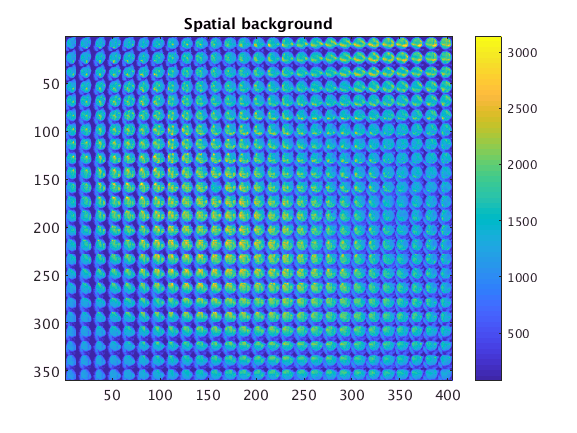

[SID_output.bg_spatial,SID_output.bg_temporal]=rank_1_factorization(sensor_movie,Input.bg_iter);
SID_output.std_image=compute_std_image(sensor_movie,SID_output.bg_spatial,SID_output.bg_temporal);

SID_output.bg_spatial = reshape(SID_output.bg_spatial,SID_output.movie_size(1:2));
SID_output.std_image = reshape(SID_output.std_image,SID_output.movie_size(1:2));

imagesc(SID_output.bg_spatial); axis image; colorbar; title('Spatial background');

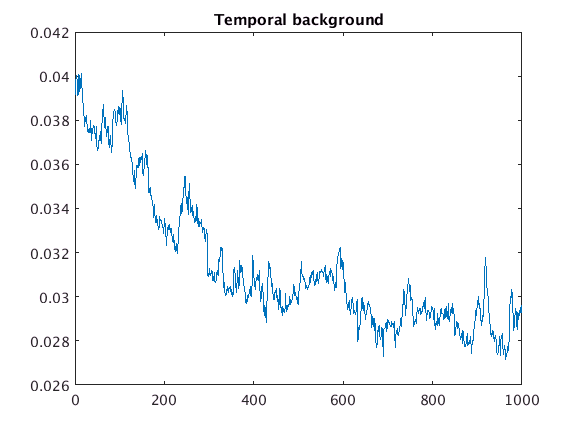

plot(SID_output.bg_temporal); title('Temporal background');

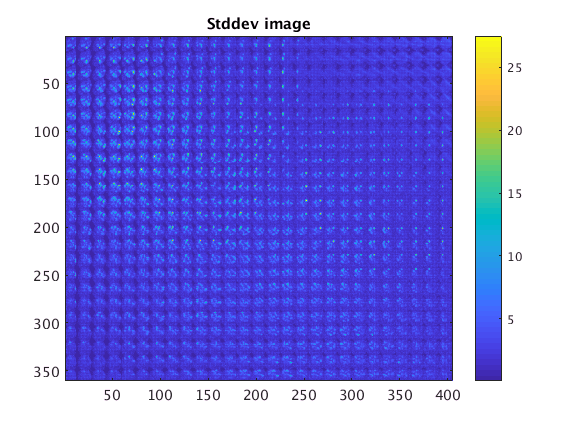

imagesc(SID_output.std_image, [prctile(SID_output.std_image(:), 0) prctile(SID_output.std_image(:), 100.0)]); title('Stddev image'); axis image; axis ij; colorbar;

## De-trend

We can see a trend in the  temporal background component *bg_temporal. *Before we proceed it is wise first to get rid of that:

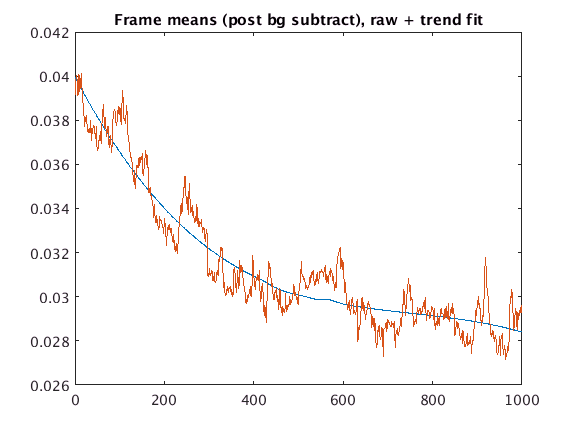

smooth_window_span = 800;

SID_output.baseline = smooth(SID_output.bg_temporal, smooth_window_span, 'sgolay', 3);
sensor_movie = sensor_movie./SID_output.baseline';
sensor_movie = sensor_movie/max(sensor_movie(:));

plot(SID_output.baseline); title('Frame means (post bg subtract), raw + trend fit');
hold on; plot(SID_output.bg_temporal); hold off

## Low-rank-non-negative-matrix factorization

max number of iterations is reached
Elapsed time is 39.600599 seconds.
opts before cross validation
        max_iter: 300
       lamb_temp: 0
       lamb_spat: 0
       lamb_orth: 1
            rank: 30
      ini_method: 'pca'
          active: [360×405 logical]
     microlenses: []
            size: [360 405]
    lamb_temp_TV: 0
      diagnostic: 1
            xval: [1×1 struct]
    lamb_orth_L2: 924.0118
       lamb_corr: 0
    lamb_orth_L1: 0
    lamb_spat_TV: 0
       pointwise: 0
             nrm: 924.0118
            hilf: [30×30 double]

help
max number of iterations is reached
Elapsed time is 0.117153 seconds.
help
max number of iterations is reached
Elapsed time is 0.110665 seconds.
help
max number of iterations is reached
Elapsed time is 0.110620 seconds.
help
max number of iterations is reached
Elapsed time is 0.099831 seconds.
help
max number of iterations is reached
Elapsed time is 0.137158 seconds.
     1

    0.1108

help
help
help
max number of iterations is reached
Ela

Iteration completed: 1, 

2, 

3, 

4, 

5, 

6, 

7, 

8, 

9, 

10, 

11, 

12, 

13, 

14, 

15, 

16, 

17, 

18, 

19, 

20, 

21, 

22, 

23, 

24, 

25, 

26, 

27, 

28, 

29, 

30, 

31, 

32, 

33, 

34, 

35, 

36, 

37, 

38, 

39, 

40, 

41, 

42, 

43, 

44, 

45, 

46, 

47, 

48, 

49, 

50, 

51, 

52, 

53, 

54, 

55, 

56, 

57, 

58, 

59, 

60, 

61, 

62, 

63, 

64, 

65, 

66, 

67, 

68, 

69, 

70, 

71, 

72, 

73, 

74, 

75, 

76, 

77, 

78, 

79, 

80, 

81, 

82, 

83, 

84, 

85, 

86, 

87, 

88, 

89, 

90, 

91, 

92, 

93, 

94, 

95, 

96, 

97, 

98, 

99, 

100, 

101, 

102, 

103, 

104, 

105, 

106, 

107, 

108, 

109, 

110, 

111, 

112, 

113, 

114, 

115, 

116, 

117, 

118, 

119, 

120, 

121, 

122, 

123, 

124, 

125, 

126, 

127, 

128, 

129, 

130, 

131, 

132, 

133, 

134, 

135, 

136, 

137, 

138, 

139, 

140, 

141, 

142, 

143, 

144, 

145, 

146, 

147, 

148, 

149, 

150, 

151, 

152, 

153, 

154, 

155, 

156, 

157, 

158, 

159, 

160, 

161, 

162, 

163, 

164, 

165, 

166, 

167, 

168, 

169, 

170, 

171, 

172, 

173, 

174, 

175, 

176, 

177, 

178, 

179, 

180, 

181, 

182, 

183, 

184, 

185, 

186, 

187, 

188, 

189, 

190, 

191, 

192, 

193, 

194, 

195, 

196, 

197, 

198, 

199, 

200, 

201, 

202, 

203, 

204, 

205, 

206, 

207, 

208, 

209, 

210, 

211, 

212, 

213, 

214, 

215, 

216, 

217, 

218, 

219, 

220, 

221, 

222, 

223, 

224, 

225, 

226, 

227, 

228, 

229, 

230, 

231, 

232, 

233, 

234, 

235, 

236, 

237, 

238, 

239, 

240, 

241, 

242, 

243, 

244, 

245, 

246, 

247, 

248, 

249, 

250, 

251, 

252, 

253, 

254, 

255, 

256, 

257, 

258, 

259, 

260, 

261, 

262, 

263, 

264, 

265, 

266, 

267, 

268, 

269, 

270, 

271, 

272, 

273, 

274, 

275, 

276, 

277, 

278, 

279, 

280, 

281, 

282, 

283, 

284, 

285, 

286, 

287, 

288, 

289, 

290, 

291, 

292, 

293, 

294, 

295, 

296, 

297, 

298, 

299, 

300, 


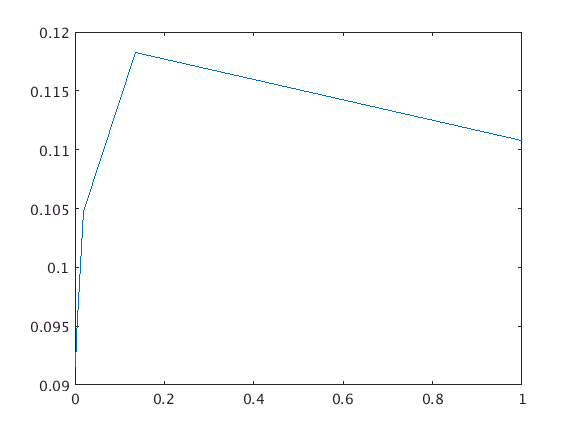

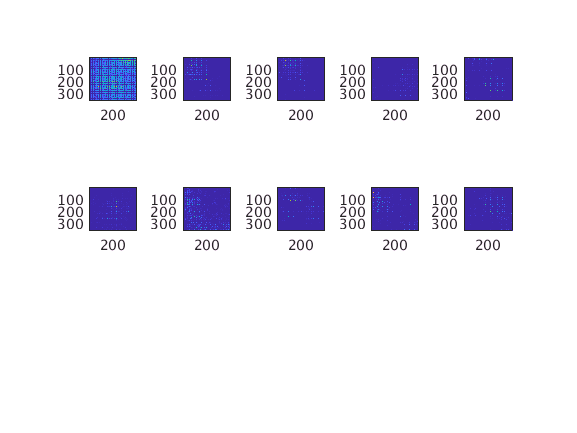

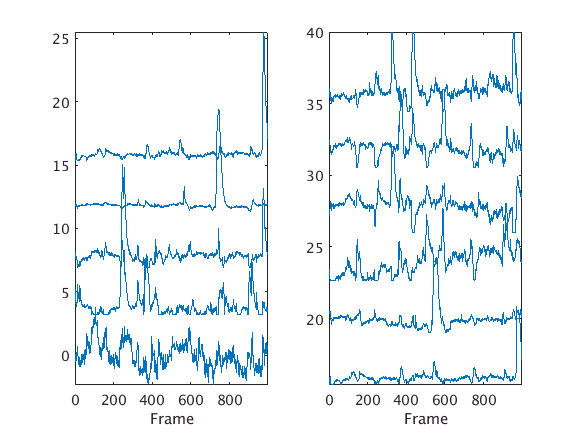

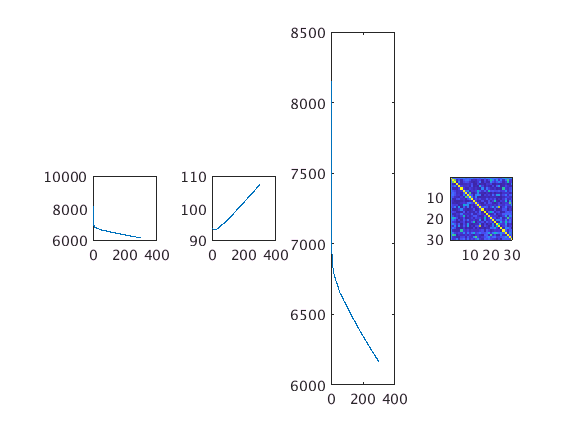

Input.nnmf_opts.rank = 30;
Input.nnmf_opts.max_iter = 600;
Input.nnmf_opts.lamb_orth_L1 = 1;
Input.nnmf_opts.ini_method='pca';
Input.nnmf_opts.active=SID_output.microlenses>0;
p=0.8;

[SID_output.S, SID_output.T]=fast_NMF(max(sensor_movie-quantile(reshape(...
    sensor_movie(SID_output.microlenses==0,:),1,[]),p),0),Input.nnmf_opts);

SID_output.S=SID_output.S(:,~isoutlier(sum(SID_output.S,1)));

